# Compresión 2D por descomposición SVD

## Cargamos la imagen original

clc, clear, close all

% Leemos el mapa de bits que sale del microscopio
I = imread('../tiltser_W.tif',6);

% Determinamos dimensiones de la imagen
nx = size(I,1); ny = size(I,2);

% Observamos su tamaño real en memoria (2 BitDepth)
imwrite(I, "../outputs/FFT_I" + ".png");

## Cálculo FTT y compresión

% Inicializamos la figura
figure(1), clf, subplot(1,5,1);
imagesc(I), axis off, colormap gray
title("STEM img")

% Computamos la FFT en 2D usando fft2()
tic;
Yt=fft2(I); 
disp([' FFT done. (' num2str(toc) 's)'])

 FFT done. (0.006567s)


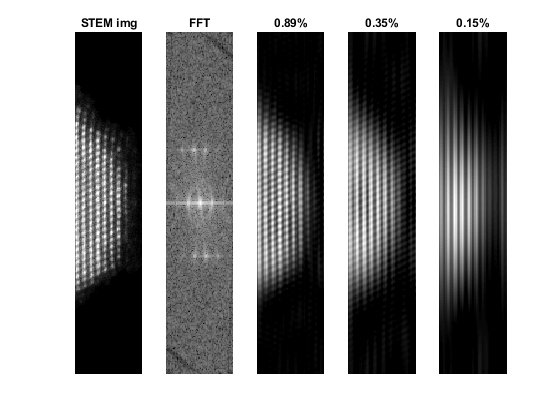


% Visualizamos los coeficientes FTT
F = log(abs(fftshift(Yt))+1);
F = mat2gray(F); % Escalado de la imagen entre 0 y 1
subplot(1,5,2)
imagesc(F), axis off
title("FFT")

% Lista de umbrales y storage de imágenes
delta_list = [0.02 0.05 0.1];
I_storage = uint16(zeros(nx,ny,length(delta_list)));

% Algoritmo de compresión para distintos umbrales
Max = max(max(abs(Yt)));
CR2 = [];
i=1;
for thresh = delta_list
    % Máscara umbral sobre los coeficientes FTT
    ind = abs(Yt) > thresh*Max; 
    Atlow = Yt .* ind;
    Ilow = uint16(ifft2(Atlow)); 
    
    % Porcentaje de coeficientes seleccionados
    count = nx*ny - sum(sum(ind));
    perc = 100 - count/(nx*ny)*100;
    
    % Observamos el tamaño real de la imagen comprimida y almacenamos
    imwrite(Ilow, "../outputs/FFT_Ilow" + num2str(perc,"%.2f") + ".png");
    I_storage(:,:,i) = Ilow;
    
    % Mostramos la imagen comprimida y su tamaño
    subplot(1,5,i+2), imagesc(Ilow), axis off
    title(num2str(perc,"%.2f") + "%",'FontSize',18)

    i = i + 1;
end

## Generador Figura 3

El siguiente fragmento de código va dirigido a contruir la Figura 3 del documento. Lo hacemos así para mostrar de forma sencilla el tamaño que ocupa cada imagen.

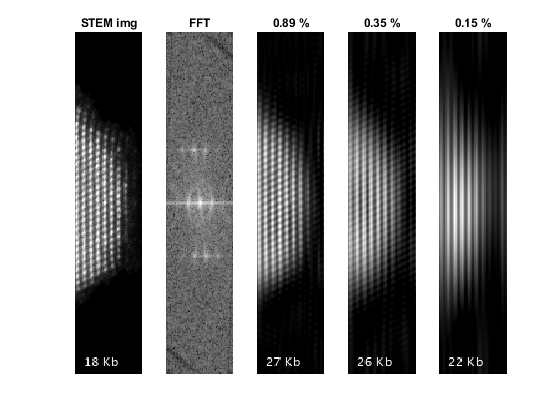

% Posición de las etiquetas
pos = [5 nx-20];

% Generamos imágenes etiquetadas
I1 = insertText(I,pos,"18 Kb",'FontSize',10,...
    'BoxOpacity',0,'TextColor','white');
I2 = insertText(I_storage(:,:,1),pos,"27 Kb",'FontSize',10,...
'BoxOpacity',0,'TextColor','white');
I3 = insertText(I_storage(:,:,2),pos,"26 Kb",'FontSize',10,...
'BoxOpacity',0,'TextColor','white');
I4 = insertText(I_storage(:,:,3),pos,"22 Kb",'FontSize',10,...
'BoxOpacity',0,'TextColor','white');

% Construimos la figura
figure(2), clf;

subplot(1,5,1);
imagesc(I1), axis off, colormap gray
title("STEM img")
subplot(1,5,2);
imagesc(F), axis off
title("FFT")
subplot(1,5,3);
imagesc(I2), axis off
title("0.89 %")
subplot(1,5,4);
imagesc(I3), axis off
title("0.35 %")
subplot(1,5,5);
imagesc(I4), axis off
title("0.15 %")